# Determine Dependencies of Services in Network

This example shows how to analyze dependencies among services in a network using the MATLAB® interface to Neo4j®. Assume that you have graph data that is stored on a Neo4j® database which represents a network. This database has seven nodes and seven relationships. Each node has only one unique property key `name` with values `Service1` through `Service7`. Each relationship has type `DEPENDS_ON`.

To find the number of services each service depends on, use the MATLAB® interface to Neo4j® and the [digraph](docid:matlab_ref.bun70tf) object. For details about the MATLAB® interface to Neo4j®, see [Working with MATLAB Interface to Neo4j](docid:database_ug.bveys16-1).

The local machine hosts the Neo4j® database with port number `7474`, user name `neo4j`, and password `matlab`. For a visual representation of the data in the database, see this figure. 

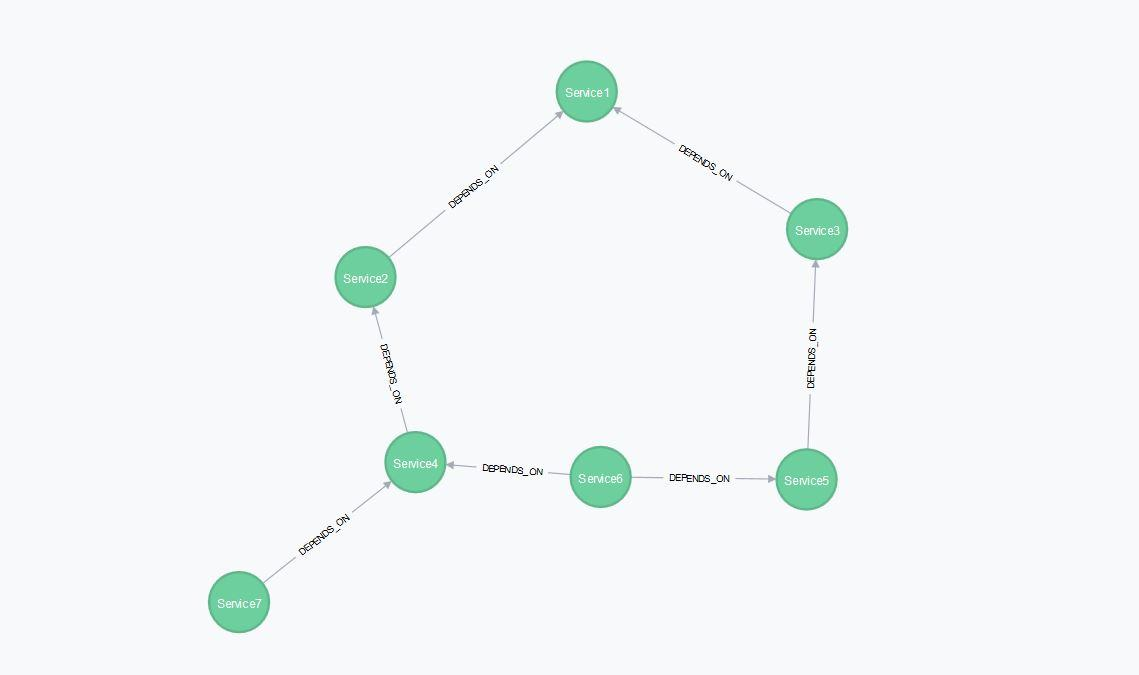

## Connect to Neo4j® Database

Create a Neo4j® connection object `neo4jconn` using the URL `http://localhost:7474/db/data`, user name `neo4j`, and password `matlab`.

url = 'http://localhost:7474/db/data';
username = 'neo4j';
password = 'matlab';

neo4jconn = neo4j(url,username,password);

Check the `Message` property of the Neo4j® connection object `neo4jconn`. The blank `Message` property indicates a successful connection.

neo4jconn.Message

## Retrieve Entire Graph

Retrieves all relationships of type `DEPENDS_ON` and all nodes associated with each relationship.

network_graphdata = searchGraph(neo4jconn,{'DEPENDS_ON'})

## Convert Graph Data to Directed Graph

Using the table `network_graphdata.Nodes`, access the `name` property for each node that appears in the `NodeData` variable of the table.

Assign the table `network_graphdata.Nodes` to `nodestable`. 

nodestable = network_graphdata.Nodes

Assign the row names for each row to `rownames`.

rownames = nodestable.Properties.RowNames

Access the `NodeData` variable from `nodestable` for each row. `nodedata` contains an array of structures.

nodedata = [nodestable.NodeData{rownames}]

To retrieve the `name` field from each structure, index into the array. `nodenames` is a cell array of character vectors that contains node names.

nodenames = {nodedata(:).name}

Create the `digraph` object `network_graph` using the `neo4jStruct2Digraph` function and the graph `network_graphdata`.

network_graph = neo4jStruct2Digraph(network_graphdata,'NodeNames',nodenames)

To see a visual representation of the graph, create a figure that displays the graph `network_graph`.

plot(network_graph,'EdgeLabel',network_graph.Edges.RelationType)

## Find Dependency Count of Each Service

Find the number of services that each service depends on in the graph `network_graph`. Determine the dependency count for each node by iterating through the nodes in the graph using a for loop. To determine the dependency count, use the `nearest` function. 

Create the table `dependency_count` that stores the count of the dependent services for each service. Sort the rows in the table by dependency count in descending order.

dependency_count = table;

for i = 1:height(network_graph.Nodes)
    nodeid = network_graph.Nodes.Name(i);
    nearest_node = nearest(network_graph,nodeid,Inf,'Direction','outgoing');
    nearest_length = length(nearest_node);
    dependency_count = [dependency_count; ...
        table(nodeid,nearest_length, ...
        'VariableNames',{'Node','Dependency_count'})];
end

dependency_count = sortrows(dependency_count,-2)

## Find All Dependencies for Specific Service

Find all the services that the service `Service6` depends on in the graph `network_graph` using the `nearest` function.

disp('Service6 depends on the following services:');
nearest(network_graph,'Service6',Inf,'Direction','outgoing')

## Close Database Connection

close(neo4jconn)

*Copyright 2018 The MathWorks, Inc.*